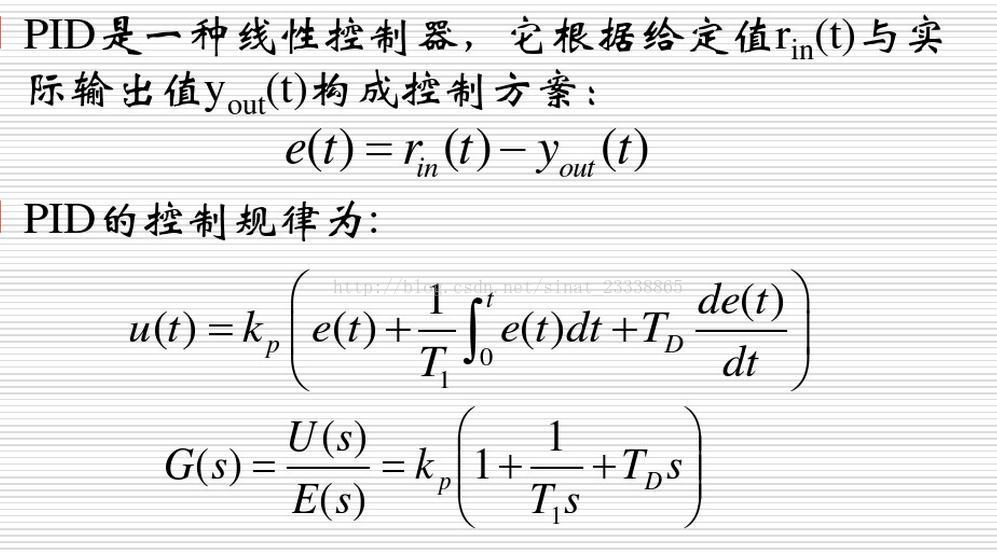

在下面这个例子中我们还会介绍到，当使用分段PID，在恰当的条件下分离积分，可以取得更好的控制效果。

原因在于在稳态误差即将满足要求时，消除了系统的滞后。因此系统超调会明显减少。本例中采样的抗积分饱和的方法是遇限削弱积分法。

改进PID算法（遇限削弱积分法）

遇限削弱积分法的原理是

当u(k)>u max 时，若e(k)>0即输出值还未到达指定值，则认为积分会带来滞后，不再积分。

当u(k)<0时，若e(k)<0即输出值超过了指定值，则认为积分会带来滞后，不再积分。

在本案例中认为u max =r(k)

改进PID算法如下（需要些两个循环，当然也可以用一个循环，将其中的PID设为一个子过程调用）：

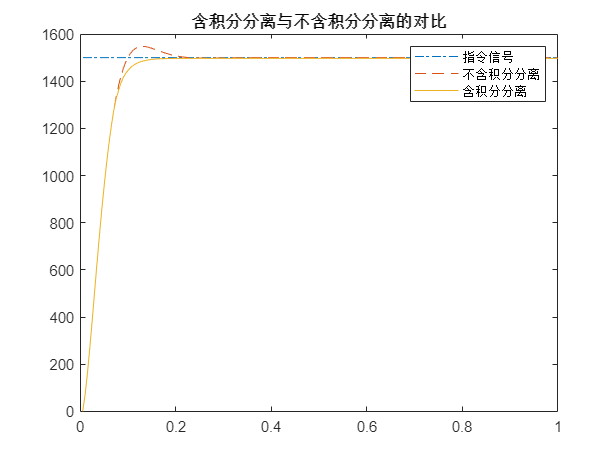

close all
ts=0.005;  %采样时间=0.005s
sys=tf(0.998,[0.021,1]);   %建立被控对象传递函数，即式4.1
dsys=c2d(sys,ts,'z');      %离散化
[num,den]=tfdata(dsys,'v');   %
e_1=0;      %前一时刻的偏差      
Ee=0;       %累积偏差
u_1=0.0;    %前一时刻的控制量
y_1=0;       %前一时刻的输出
%PID参数
kp=0.22;    
ki=0.13;
kd=0;
u=zeros(1,1000);
time=zeros(1,1000);
for k=1:1:1000
    time(k)=k*ts;   %时间参数
    r(k)=1500;      %给定量
    y(k)=-1*den(2)*y_1+num(2)*u_1+num(1)*u(k);
    e(k)=r(k)-y(k);   %偏差
    u(k)=kp*e(k)+ki*Ee+kd*(e(k)-e_1);   
    Ee=Ee+e(k);    
    u_1=u(k);    
    y_1=y(k);    
    e_1=e(k);
end
p1=plot(time,r,'-.');xlim([0,1]);hold on;
p2=plot(time,y,'--');xlim([0,1]);
hold on;

a=1;%控制积分分离的二值数
e_1=0;Ee=0;u_1=0.0;y_1=0;%重新初始化       
for k=1:1:1000
    time(k)=k*ts;   %时间参数
    r(k)=1500;      %给定量
    y(k)=-1*den(2)*y_1+num(2)*u_1;
    e(k)=r(k)-y(k);   %偏差
    u(k)=kp*e(k)+ki*Ee+kd*(e(k)-e_1);   
     if ((u(k)>r(k)) && (e(k)>0))||((u(k)<0) && (e(k)<0))
         a=0;
     else 
         a=1;
     end     
    Ee=Ee+a*e(k);    
    u_1=u(k);    
    y_1=y(k);    
    e_1=e(k);
end
p3=plot(time,y,'-');xlim([0,1]);
title('含积分分离与不含积分分离的对比');
legend([p1,p2,p3],'指令信号','不含积分分离','含积分分离');

**5.simulink仿真**

需要的模块名称（不区分大小写）如下：

- gain（参数分别为0.22和0.13/0.005）

- sum（参数分别为"|±"和"|++"）

- integrator

- scope

注意：本文使用的是离散PID仿真，而simulink使用的是连续系统仿真，

**转换PID参数时P参数不变，I 参数应该除以仿真间隔 Ts=0.005，D 参数应该乘 Ts。**

————————————————

版权声明：本文为CSDN博主「非线性光学元件」的原创文章，遵循CC 4.0 BY-SA版权协议，转载请附上原文出处链接及本声明。

原文链接：https://blog.csdn.net/weixin_44044411/article/details/85891109